# XTD_A4: Cross Epoch Decodability

% load('.\XTD_WT_PI_PO_RawLFP.mat');
% load('D:\WorkBigDataFiles\PFC\XTD_All_PO_PO.mat');
% load('D:\WorkBigDataFiles\PFC\XTD_DL_PI_PO.mat');

cMap = load('roma.mat'); % flip
cMap = cMap.(cell2mat(fieldnames(cMap)));
cMap = flipud(cMap);
cMapNanW = cMap;
cMapNanW(1,:) = ones(1,3);
%#ok<*UNRCH>
rbDivMap = diverging_map(0:0.01:1,[0 0.4 0.8], [0.8 0 0.4]);

objTimeVect = mlb.obsvTimeVect-mlb.obsvTimeVect(1);


## Compile Data

trInt_DecPPF = cell(mlb.seqLength, length(fileDirs));
trIntCON_DecPPF = cell(mlb.seqLength, length(fileDirs));
trInt_TstTrl = cell(mlb.seqLength, length(fileDirs));
trIntCON_TstTrl = cell(mlb.seqLength, length(fileDirs));

trTrl_DecInt = cell(mlb.seqLength, length(fileDirs));
trTrl_DecIntCON = cell(mlb.seqLength, length(fileDirs));
trTrl_TstInt = cell(mlb.seqLength, length(fileDirs));
trTrl_TstIntCON = cell(mlb.seqLength, length(fileDirs));

for ani = 1:length(fileDirs)
    for pos = 1:mlb.seqLength
        % Extract Variables
%         curPos_D = xtd_D{pos,pos,ani};
        curPos_D = xtd_HR{pos,pos,ani};
        if pos~=1
%             prevPos_D = xtd_D{pos,pos-1,ani};
            prevPos_D = xtd_HR{pos,pos-1,ani};
        else
            prevPos_D = nan(size(curPos_D));
        end
        if pos~=4
%             nextPos_D = xtd_D{pos,pos+1,ani};
            nextPos_D = xtd_HR{pos,pos+1,ani};
        else
            nextPos_D = nan(size(curPos_D));
        end
        curPos_TrialMask = mask_Trial{pos,ani};
        curPos_IntPreMask = mask_PreInt{pos,ani};
        curPos_IntPreMaskCON = mask_PreIntCON{pos,ani};
        curPos_IntPstMask = mask_PstInt{pos,ani};
        curPos_IntPstMaskCON = mask_PstIntCON{pos,ani};
        if strcmp(alignment{1}, 'PokeIn')
            curPos_IntMask = curPos_IntPreMask;
            curPos_IntMaskCON = curPos_IntPreMaskCON;
        else
            curPos_IntMask = curPos_IntPstMask;
            curPos_IntMaskCON = curPos_IntPstMaskCON;
        end
        % Create Trial Variables
        curTrl_trInt_DecPPF = nan(length(mlb.obsvTimeVect),size(curPos_D,3),3);
        curTrl_trIntCON_DecPPF = nan(length(mlb.obsvTimeVect),size(curPos_D,3),3);
        curTrl_trInt_TstTrl = nan(3,size(curPos_D,3));
        curTrl_trIntCON_TstTrl = nan(3,size(curPos_D,3));

        curTrl_trTrl_DecInt = nan(length(mlb.obsvTimeVect),size(curPos_D,3),2);
        curTrl_trTrl_DecIntCON = nan(length(mlb.obsvTimeVect),size(curPos_D,3),2);
        curTrl_trTrl_TstInt = nan(2,size(curPos_D,3));
        curTrl_trTrl_TstIntCON = nan(2,size(curPos_D,3));
        % Analyze Trials
        for trl = 1:size(curPos_D,3)
            % Define Trial Data
            curTrl_D = curPos_D(:,:,trl);
            curTrl_Dprev = prevPos_D(:,:,trl);
            curTrl_Dnxt = nextPos_D(:,:,trl);
            % Collect Data - Interval Trained Models
            curTrl_trInt_DecPPF(:,trl,:) = cat(3,mean(curTrl_Dprev(:,curPos_IntMask(:,trl)), 2, 'omitnan'),...
                mean(curTrl_D(:,curPos_IntMask(:,trl)), 2, 'omitnan'),...
                mean(curTrl_Dnxt(:,curPos_IntMask(:,trl)), 2, 'omitnan'));
            curTrl_trIntCON_DecPPF(:,trl,:) = cat(3,mean(curTrl_Dprev(:,curPos_IntMaskCON(:,trl)), 2, 'omitnan'),...
                mean(curTrl_D(:,curPos_IntMaskCON(:,trl)), 2, 'omitnan'),...
                mean(curTrl_Dnxt(:,curPos_IntMaskCON(:,trl)), 2, 'omitnan'));
            curTrl_trInt_TstTrl(:,trl) = [mean(curTrl_Dprev(curPos_TrialMask(:,trl),curPos_IntMask(:,trl)), 'all', 'omitnan');...
                mean(curTrl_D(curPos_TrialMask(:,trl),curPos_IntMask(:,trl)), 'all', 'omitnan');...
                mean(curTrl_Dnxt(curPos_TrialMask(:,trl),curPos_IntMask(:,trl)), 'all', 'omitnan')];
            curTrl_trIntCON_TstTrl(:,trl) = [mean(curTrl_Dprev(curPos_TrialMask(:,trl), curPos_IntMaskCON(:,trl)), 'all', 'omitnan');...
                mean(curTrl_D(curPos_TrialMask(:,trl),curPos_IntMaskCON(:,trl)), 'all','omitnan');...
                mean(curTrl_Dnxt(curPos_TrialMask(:,trl),curPos_IntMaskCON(:,trl)), 'all', 'omitnan')];
            % Collect Data - Trial Trained Models
            temp_trTrl_DecPre = mean(curTrl_D(curPos_IntPreMask(:,trl),curPos_TrialMask(:,trl)), 1, 'omitnan');
            temp_trTrl_DecPst = mean(curTrl_D(curPos_IntPstMask(:,trl),curPos_TrialMask(:,trl)), 1, 'omitnan');
            temp_trTrl_DecPreCON = mean(curTrl_D(curPos_IntPreMaskCON(:,trl),curPos_TrialMask(:,trl)), 1, 'omitnan');
            temp_trTrl_DecPstCON = mean(curTrl_D(curPos_IntPstMaskCON(:,trl),curPos_TrialMask(:,trl)), 1, 'omitnan');

            if strcmp(alignment{1}, 'PokeIn')
                curTrl_trTrl_DecInt(1:sum(curPos_TrialMask(:,trl)),trl,:) = cat(3,temp_trTrl_DecPre',temp_trTrl_DecPst');
                curTrl_trTrl_DecIntCON(1:sum(curPos_TrialMask(:,trl)),trl,:) = [temp_trTrl_DecPreCON',temp_trTrl_DecPstCON'];
            else
                curTrl_trTrl_DecInt(end-sum(curPos_TrialMask(:,trl))+1:end,trl,:) = [temp_trTrl_DecPre',temp_trTrl_DecPst'];
                curTrl_trTrl_DecIntCON(end-sum(curPos_TrialMask(:,trl))+1:end,trl,:) = [temp_trTrl_DecPreCON',temp_trTrl_DecPstCON'];
            end

            curTrl_trTrl_TstInt(:,trl) = [mean(curTrl_D(curPos_IntPreMask(:,trl),curPos_TrialMask(:,trl)), 'all', 'omitnan');...
                mean(curTrl_D(curPos_IntPstMask(:,trl),curPos_TrialMask(:,trl)), 'all', 'omitnan')];
            curTrl_trTrl_TstIntCON(:,trl) = [mean(curTrl_D(curPos_IntPreMaskCON(:,trl),curPos_TrialMask(:,trl)), 'all', 'omitnan');...
                 mean(curTrl_D(curPos_IntPstMaskCON(:,trl),curPos_TrialMask(:,trl)), 'all', 'omitnan')];
        end
        trInt_DecPPF{pos,ani} = curTrl_trInt_DecPPF;
        trIntCON_DecPPF{pos,ani} = curTrl_trIntCON_DecPPF;
        trInt_TstTrl{pos,ani} = curTrl_trInt_TstTrl;
        trIntCON_TstTrl{pos,ani} = curTrl_trIntCON_TstTrl;

        trTrl_DecInt{pos,ani} = curTrl_trTrl_DecInt;
        trTrl_DecIntCON{pos,ani} = curTrl_trTrl_DecIntCON;
        trTrl_TstInt{pos,ani} = curTrl_trTrl_TstInt;
        trTrl_TstIntCON{pos,ani} = curTrl_trTrl_TstIntCON;
    end
end

trialLIGHTlat = lat_PrtLight(2:end,:)';
% trialLIGHTlat = cell2mat(trialLIGHTlat(:)');
trialPIlat = lat_TrlStart(:);
% trialPIlat = cell2mat(trialPIlat(:)');
trialSIGlat = lat_RwdSig(:);
% trialSIGlat = cell2mat(trialSIGlat(:)');
trialPOlat = lat_TrlEnd(:);
% trialPOlat = cell2mat(trialPOlat(:)');
trialRWDlat = lat_Rwd(:);
% trialRWDlat = cell2mat(trialRWDlat(:)');
nxtTrlLats = lat_NextTrl(:);
% nxtTrlLats = cell2mat(nxtTrlLats(:)');
prevTrlLats = lat_PrevTrl(:);
% prevTrlLats = cell2mat(prevTrlLats(:)');


## Plot Interval Training - Decode Past/Present/Future

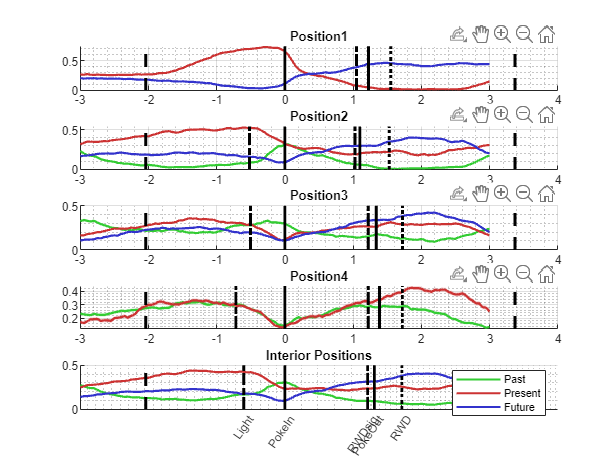

cur_Dec = trInt_DecPPF;
cur_Dec = trIntCON_DecPPF;
figure;
for pos = 1:mlb.seqLength
    curPos_IntPPF = cell2mat(cur_Dec(pos,:));
    subplot(5,1,pos);
    mlb.PlotMeanVarLine(mlb.obsvTimeVect, curPos_IntPPF(:,:,1), 2, 0, [0.2 0.8 0.2]);
    mlb.PlotMeanVarLine(mlb.obsvTimeVect, curPos_IntPPF(:,:,2), 2, 0, [0.8 0.2 0.2]);
    mlb.PlotMeanVarLine(mlb.obsvTimeVect, curPos_IntPPF(:,:,3), 2, 0, [0.2 0.2 0.8]);
    if pos~=1
        plot(repmat(median(cell2mat(lat_PrtLight(pos,:))), [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 2);
    end
    plot(repmat(median(cell2mat(lat_TrlStart(pos,:))), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
    plot(repmat(median(cell2mat(lat_RwdSig(pos,:))), [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 2);
    plot(repmat(median(cell2mat(lat_TrlEnd(pos,:))), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
    plot(repmat(median(cell2mat(lat_Rwd(pos,:))), [1,2]), get(gca,'ylim'), ':k', 'linewidth', 2);
    if strcmp(endTrialBound, 'RWD')
        plot( repmat(median(cell2mat(trialRWDlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    elseif strcmp(endTrialBound, 'PO')
        plot(repmat(median(cell2mat(trialPOlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    elseif strcmp(endTrialBound, 'RS')
        plot(repmat(median(cell2mat(trialSIGlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    end
    plot(repmat(median(cell2mat(trialPIlat(:)')) + median(cell2mat(prevTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    title(sprintf('Position%i',pos));
    grid on;
    grid minor;
end

temp_Dec = cur_Dec;
tit = 'All Trials';
temp_Dec([1,mlb.seqLength],:) = []; tit = 'Interior Positions';
temp_Dec = cell2mat(temp_Dec(:)');
p=nan(1,3);
subplot(5,1,5)
p(1) = mlb.PlotMeanVarLine(mlb.obsvTimeVect, temp_Dec(:,:,1), 2, 0, [0.2 0.8 0.2]);
p(2) = mlb.PlotMeanVarLine(mlb.obsvTimeVect, temp_Dec(:,:,2), 2, 0, [0.8 0.2 0.2]);
p(3) = mlb.PlotMeanVarLine(mlb.obsvTimeVect, temp_Dec(:,:,3), 2, 0, [0.2 0.2 0.8]);
plot(repmat(median(cell2mat(trialLIGHTlat(:)')), [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 2);
plot(repmat(median(cell2mat(trialPIlat(:)')), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
plot(repmat(median(cell2mat(trialSIGlat(:)')), [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 2);
plot(repmat(median(cell2mat(trialPOlat(:)')), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
plot(repmat(median(cell2mat(trialRWDlat(:)')), [1,2]), get(gca,'ylim'), ':k', 'linewidth', 2);
if strcmp(endTrialBound, 'RWD')
    plot(repmat(median(cell2mat(trialRWDlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
elseif strcmp(endTrialBound, 'PO')
    plot(repmat(median(cell2mat(trialPOlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
elseif strcmp(endTrialBound, 'RS')
    plot(repmat(median(cell2mat(trialSIGlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
end
plot(repmat(median(cell2mat(trialPIlat(:)')) + median(cell2mat(prevTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
set(gca,'xtick', [median(cell2mat(trialLIGHTlat(:)')),...
    median(cell2mat(trialPIlat(:)')),...
    median(cell2mat(trialSIGlat(:)')),...
    median(cell2mat(trialPOlat(:)')),...
    median(cell2mat(trialRWDlat(:)'))], 'xticklabels', [{'Light'}, {'PokeIn'}, {'RWDsig'}, {'PokeOut'}, {'RWD'}], 'Xticklabelrotation',55);
title(tit);
legend(p, [{'Past'}, {'Present'}, {'Future'}]);
grid on;
grid minor;